# **Event-Based Controller**

This event-based controller will change the desired torso angle θd3 at the beginning of every walking step to regulate the average hip velocity.

clc; clear all; close all;
HW5_sol();

## [HW6] 

### Running the Simulation

% Set constants
odeOpts = odeset('Events', @three_link_event);
t_sol = [] ; x_sol = [] ;
tspan = [0 3] ;
Nsteps = 100 ;
x0 = [-0.3827, 0.9239, 2.2253, 3.0107, 0.5236, 0.8653, 0.3584, -1.0957, -2.3078, 2.0323]' ;


%--------------------------------------
% first guess: th3d = pi/6
params.th3d = pi/6;
v_avg       = [];
error       = [];
derror      = [];
sumerror    = [];

Kp = 0.049;
Kd = 0.07;
Ki = 0.0000001;

%--------------------------------------


% Simulate multiple steps
for i = 1:Nsteps
    % Continuous time dynamics
    [t, x] = ode45(@three_link_dynamics, tspan, x0, odeOpts, params);

    % Impact Map
    qminus = x(end, 1:5)';
    dqminus = x(end, 6:end)';
    qPlus = params.R*qminus;
    dqPlus = params.R*dqPlus_gen([qminus;dqminus]);

    % Reinitalize for next step
    x0 = [qPlus;dqPlus];
    tspan = t(end) + [0 3] ;

    % Save state trajectory
    t_sol = [t_sol; t];
    x_sol = [x_sol; x];

    %--------------------------------------
    % ...
    v_avg    = [v_avg; (x(end,1)-x(1,1))/(t(end)-t(1)) ];
    
    error    = [error; 0.5-v_avg(end)];
    if i==1 derror=0; else derror = [derror;error(end)-error(end-1)]; end
    sumerror = [sumerror;sum(error)];

    params.th3d = params.th3d + (error(end)*Kp + derror(end)*Kd + sumerror(end)*Ki);


    %--------------------------------------
    
end

% animateThreeLink(t_sol, x_sol)

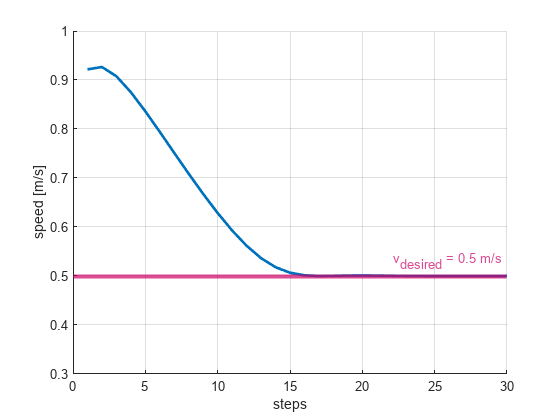

clf;
figure(1)
hold on
grid on
plot(v_avg,'LineWidth',2);
yline(0.5,'-','v_{desired} = 0.5 m/s','LineWidth',3,Color = [.80 0 .40]);
ylim([0.3,1]);
xlim([0,30]);
xlabel('steps');
ylabel('speed [m/s]');

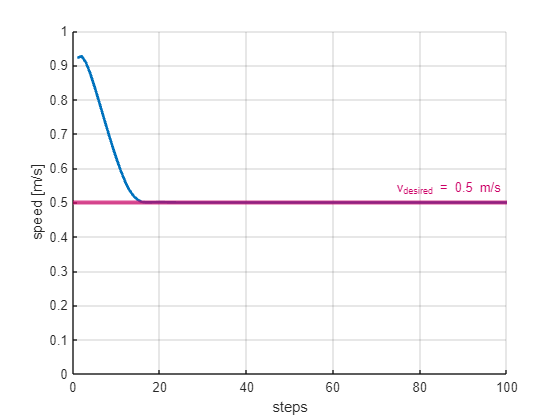

clf;
figure(2)
hold on
grid on
plot(v_avg,'LineWidth',2);
yline(0.5,'-','v_{desired} = 0.5 m/s','LineWidth',3,Color = [.80 0 .40]);
ylim([0,1]);
xlabel('steps');
ylabel('speed [m/s]');

for i = 1:length(v_avg)
    if all(round(v_avg(i:end),4) == 0.5)
        disp("The robot is reaching the desired speed after "+ i +" steps!");
        break
    end
end

The robot is reaching the desired speed after 25 steps!


## Functions

Create Dynamics and Events Function:

function dx = three_link_dynamics(t, x, params)
    u = three_link_io_control(x, params);
    dx = fvec_gen(x) + gvec_gen(x)*u;
end

% Event function
function [value,isterminal,direction] = three_link_event(t, x, params)
    th = params.T*x(1:5) + params.d;
    value = th(3) - params.th1d;
    isterminal = 1;
    direction = 1; 
end

Create Controller Functions:

% Controller Functions
function ret = phi_a(x1, x2, a)
    ret = x1 + 1/(2-a) * sign(x2) * abs(x2)^(2-a) ;
end

function ret = psi_a(x1, x2, a)
    ret = -sign(x2)*abs(x2)^a - sign(phi_a(x1,x2,a))*abs(phi_a(x1,x2,a))^(a/(2-a)) ;
end

function u = three_link_io_control(x, params)
    y = y_gen(x, params.th3d);
    dy = Lfy_gen(x);
    LgLfy = LgLfy_gen(x);
    Lf2y = Lf2y_gen(x);
    
    y1 = y(1); y2 = y(2);
    dy1 = dy(1); dy2 = dy(2);
    
    e = params.eps;  a = params.a ;
    v = [psi_a(y1, e*dy1, a);
         psi_a(y2, e*dy2, a)]./e^2;
    
    u = inv(LgLfy)*(-Lf2y + v);
end